#### `N foot position: `$r_{f,i}$

clear all; clc; close all;
num_steps = 2;
foot_W = 0.05;
foot_H = 0.15;
foot_stride_y = 0.05;
foot_stride_x = 0.15;
x_torso = foot_W + foot_stride_y;
step_length = foot_stride_x + foot_H;

is_left = false;
swingHeight = 0.1;

msup = 5;
mswg = 5;
mpend = 50;
mfeet = 10;
mtotal = 60;
g = 9.807;
z_robot = 0.78;
omega = sqrt(g/z_robot);

t_step = 0.8;
t_sample = 0.01;
tDS = 0.1;
tSS = t_step - tDS;
t_ini = 2;
t_fnl = 2;

traj_ds = struct('index', {}, 'p_ds', {}, 'state', {});

t = 0:t_sample:t_step*(num_steps+2) + t_ini + t_fnl - t_sample;

if is_left
    foot_plants = [0 x_torso 0; 0 -x_torso 0];
    for i=3:num_steps+3
        foot_plants(i, :) = [(i-2)*step_length (-1)^(i-1)*x_torso 0];
    end
else
    foot_plants = [0 -x_torso 0; 0 x_torso 0];
    for i=3:num_steps+3
        foot_plants(i, :) = [(i-2)*step_length (-1)^(i)*x_torso 0];
    end
end
foot_plants(end+1, :) = [1,-1, 1] .* foot_plants(end,:);

#### 
$$P^{\;\mathrm{ref}}$$


p_ref = zeros(t_ini/t_sample,3);

for ith = 1:num_steps+2
    indx =  (t_step*(ith-1)/t_sample);
    
    init_time = t_ini + indx*t_sample + t_sample;
    final_time = init_time + t_step - t_sample;
    swingfootpos0 = foot_plants(ith, :);
    swingfootpos1 = foot_plants(ith+2, :);
    [qswing, dqswing, ddqswing] = getSwingFootTraj(swingfootpos0', swingfootpos1', swingHeight, ...
                            init_time, final_time,t_sample);
                        
    for j = 1:t_step/t_sample
        p_ref(int32(t_ini/t_sample)+indx+j,:) = foot_plants(ith+1,:);
        
        swing_traj(int32(t_ini/t_sample)+indx+j,:) = [qswing(:,j)', dqswing(:,j)', ddqswing(:,j)'];
        
        Mfeet(int32(t_ini/t_sample)+indx+j,1) = mswg*(qswing(1,j) - p_ref(int32(t_ini/t_sample)+indx+j,1))*(g + ddqswing(3,j)) ...
            - mswg*(ddqswing(1,j))*(qswing(3,j) - z_robot);
        Mfeet(int32(t_ini/t_sample)+indx+j,2) = mswg*(qswing(2,j) - p_ref(int32(t_ini/t_sample)+indx+j,2))*(g + ddqswing(3,j)) ...
           - mswg*(ddqswing(2,j))*(qswing(3,j) - z_robot);
        
        zmp_feet(int32(t_ini/t_sample)+indx+j,1) = Mfeet(int32(t_ini/t_sample)+indx+j,1)/(mfeet*g) + p_ref(int32(t_ini/t_sample)+indx+j,1);
        zmp_feet(int32(t_ini/t_sample)+indx+j,2) = Mfeet(int32(t_ini/t_sample)+indx+j,2)/(mfeet*g) + p_ref(int32(t_ini/t_sample)+indx+j,2);

        zmp_pend(int32(t_ini/t_sample)+indx+j,1) = (mtotal/mpend)*p_ref(int32(t_ini/t_sample)+indx+j,1) - (mfeet/mpend)*zmp_feet(int32(t_ini/t_sample)+indx+j,1) ;
        zmp_pend(int32(t_ini/t_sample)+indx+j,2) = (mtotal/mpend)*p_ref(int32(t_ini/t_sample)+indx+j,2) - (mfeet/mpend)*zmp_feet(int32(t_ini/t_sample)+indx+j,2) ;

    end
end
p_ref(end+1:end+t_fnl/t_sample,:) = ones(t_fnl/t_sample,3).*[foot_plants(ith+1,1) 0 0];
swing_traj(end+1:end+t_fnl/t_sample,:) = ones(t_fnl/t_sample,9).*[foot_plants(ith+1,1) 0 0 0 0 0 0 0 0];
zmp_feet(end+1:end+t_fnl/t_sample,:) = ones(t_fnl/t_sample,2).*[foot_plants(ith+1,1) 0];
zmp_pend(end+1:end+t_fnl/t_sample,:) = ones(t_fnl/t_sample,2).*[foot_plants(ith+1,1) 0];
zmp_total = p_ref(:,1:2);
p_ref(:,1:2) = zmp_pend;

#### `control loop`

A = [1 t_sample (t_sample^2)/2;
     0    1       t_sample;
     0    0           1];
B = [(t_sample^3)/6; (t_sample^2)/2; t_sample];
C = [1 0 -z_robot/g];
NL = 1.6/t_sample;

Qe = 1; R = 1e-6;
Qx = zeros(3,3);
B_ = [C*B; B];
I_ = [1; zeros(3,1)];
F_ = [C*A; A];
Q_ = [Qe zeros(1,3); zeros(3,1) Qx];
A_ = [I_ F_];

[K_,L,G,info] = idare(A_,B_,Q_,R,[],[]);

GI = (B_'*K_*B_ + R)\(B_'*K_*I_);
Gx = (B_'*K_*B_ + R)\(B_'*K_*F_);
Ac_ = A_-B_*inv(R+B_'*K_*B_)*B_'*K_*A_;

CoM = struct('x', zeros(3,length(t)-NL), 'y', zeros(3,length(t)-NL));
p = zeros(length(t)-NL,2);
u = zeros(length(t)-NL,2);

for l = 1:NL
    if l == 1;
        X_(:,l) = -Ac_'*K_*I_;
    else
        X_(:,l) = Ac_'*X_(:,l-1);
    end
end

for k = 1:length(t)-NL
    err = [0 0];
    p(k,:) = C*[CoM.x(:,k) CoM.y(:,k)];
    for i = 1:k
        err = err + p(i,:)-p_ref(i,1:2);
    end
    preview_term = [0 0];
    for j = 1:NL
        if j==1
            Gp(j) = -GI;
        else
            Gp(j) = (B_'*K_*B_ + R)\(B_'*X_(:,j-1));
        end
        preview_term = preview_term + Gp(j)*p_ref(k+j,1:2); 
    end
    u(k,:) = -GI*err - Gx*[CoM.x(:,k) CoM.y(:,k)] - preview_term;
    CoM.x(:,k+1) = A*CoM.x(:,k) + B*u(k,1);
    CoM.y(:,k+1) = A*CoM.y(:,k) + B*u(k,2);
end
DCM.x = CoM.x(1,:) + CoM.x(2,:)/omega;
DCM.y = CoM.y(1,:) + CoM.y(2,:)/omega;

#### `plot trajectories`

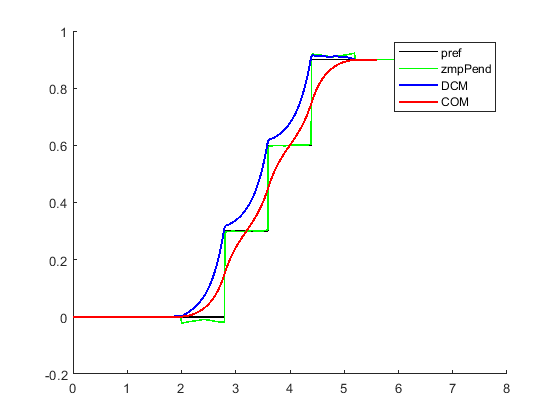

figure
hold on
% set(gca, 'DataAspectRatio',[3 1 1])
% plot(t, p_ref(:,1),'b','LineWidth', 1.2)
% plot(t, zmp_feet(:,1),'MarkerFaceColor',[0 .7 .7],'LineWidth', 1.2)
plot(t, zmp_total(:,1),'k','LineWidth', 1.2)
plot(t, zmp_pend(:,1),'g','LineWidth', 1.2)
% plot(t, swing_traj(:,1),'m','LineWidth', 1.2)
% plot(t(1:end-NL), p(:,1),'c','LineWidth', 1.2)
plot(t(1:end-NL+1), DCM.x,'b','LineWidth', 1.5)
plot(t(1:end-NL+1), CoM.x(1,:),'r','LineWidth', 1.5)
legend('pref','zmpPend','DCM','COM')

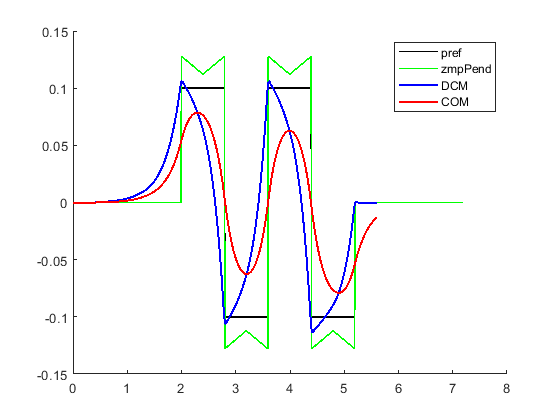


figure
hold on
% set(gca, 'DataAspectRatio',[10 1 1])
% plot(t, p_ref(:,2),'y','LineWidth', 1.5)
% plot(t, zmp_feet(:,2),'MarkerFaceColor',[0 .7 .7],'LineWidth', 1.2)
plot(t, zmp_total(:,2),'k','LineWidth', 1.2)
plot(t, zmp_pend(:,2),'g','LineWidth', 1.2)
% plot(t, swing_traj(:,2),'m','LineWidth', 1.2)
% plot(t(1:end-NL), p(:,2),'c','LineWidth', 1.2)
plot(t(1:end-NL+1), DCM.y,'b','LineWidth', 1.5)
plot(t(1:end-NL+1), CoM.y(1,:),'r','LineWidth', 1.5)
legend('pref','zmpPend','DCM','COM')